# **Problem E8.5**

## **i.**

syms x1 x2
f = (x1 + x2)^4 - 12*x1*x2 + x1 + x2 + 1;
g = gradient(f, [x1, x2])

$$g = \left(\begin{array}{c} 4\,{\left(x_{1}+x_{2}\right)}^{3}-12\,x_{2}+1\\ 4\,{\left(x_{1}+x_{2}\right)}^{3}-12\,x_{1}+1 \end{array}\right)$$

x_1 = [-0.6504; -0.6504];
x_2 = [0.085; 0.085];
x_3 = [0.5655; 0.5655];
subs(g, [x1; x2], x_1)

$$ans = \left(\begin{array}{c} \frac{138187}{244140625}\\ \frac{138187}{244140625} \end{array}\right)$$

subs(g, [x1; x2], x_2)

$$ans = \left(\begin{array}{c} -\frac{87}{250000}\\ -\frac{87}{250000} \end{array}\right)$$

subs(g, [x1; x2], x_3)

$$ans = \left(\begin{array}{c} \frac{231091}{250000000}\\ \frac{231091}{250000000} \end{array}\right)$$

Gradients are very close to 0 at these points so these can be considered stationary points.

## ii.

We will first calculate the Hessian matrix and then we will evaluate it at each of the stationary points. After that we will obtain the eigenvalues and decide what type of extrema each point corresponds to.

h = hessian(f, [x1, x2])

$$h = \left(\begin{array}{cc} 12\,{\left(x_{1}+x_{2}\right)}^{2} & 12\,{\left(x_{1}+x_{2}\right)}^{2}-12\\ 12\,{\left(x_{1}+x_{2}\right)}^{2}-12 & 12\,{\left(x_{1}+x_{2}\right)}^{2} \end{array}\right)$$

h1 = subs(h, [x1; x2], x_1)

$$h1 = \left(\begin{array}{cc} \frac{7931628}{390625} & \frac{3244128}{390625}\\ \frac{3244128}{390625} & \frac{7931628}{390625} \end{array}\right)$$

eig(h1)

$$ans = \left(\begin{array}{c} 12\\ \frac{11175756}{390625} \end{array}\right)$$

At $x^1$ we can observe that both of the eigenvalues are positive, indicating that this points corresponds to a strong minimum.

h2 = subs(h, [x1; x2], x_2)

$$h2 = \left(\begin{array}{cc} \frac{867}{2500} & -\frac{29133}{2500}\\ -\frac{29133}{2500} & \frac{867}{2500} \end{array}\right)$$

eig(h2)

$$ans = \left(\begin{array}{c} -\frac{14133}{1250}\\ 12 \end{array}\right)$$

At $x^2$ we have one positive and one negative eignevalue which implies that this point corresponds to saddle point.

h3 = subs(h, [x1; x2], x_3)

$$h3 = \left(\begin{array}{cc} \frac{3837483}{250000} & \frac{837483}{250000}\\ \frac{837483}{250000} & \frac{3837483}{250000} \end{array}\right)$$

eig(h3)

$$ans = \left(\begin{array}{c} 12\\ \frac{2337483}{125000} \end{array}\right)$$

Finally at $x^3$ the hessian is shown to be positive-definite because both eigenvalues are positive, therefore this point is also a strong minimum.

## iii.

t1 = taylor(f, [x1; x2], x_1, 'Order', 3)

$$t1 = \frac{138187\,x_{1}}{244140625}+\frac{138187\,x_{2}}{244140625}+\frac{3244128\,\left(x_{1}+\frac{813}{1250}\right)\,\left(x_{2}+\frac{813}{1250}\right)}{390625}+\frac{3965814\,{\left(x_{1}+\frac{813}{1250}\right)}^{2}}{390625}+\frac{3965814\,{\left(x_{2}+\frac{813}{1250}\right)}^{2}}{390625}-\frac{383479119383}{152587890625}$$

t2 = taylor(f, [x1; x2], x_2, 'Order', 3)

$$t2 = \frac{867\,{\left(x_{1}-\frac{17}{200}\right)}^{2}}{5000}-\frac{87\,x_{2}}{250000}-\frac{29133\,\left(x_{1}-\frac{17}{200}\right)\,\left(x_{2}-\frac{17}{200}\right)}{2500}-\frac{87\,x_{1}}{250000}+\frac{867\,{\left(x_{2}-\frac{17}{200}\right)}^{2}}{5000}+\frac{108419437}{100000000}$$

t3 = taylor(f, [x1; x2], x_3, 'Order', 3)

$$t3 = \frac{231091\,x_{1}}{250000000}+\frac{231091\,x_{2}}{250000000}+\frac{837483\,\left(x_{1}-\frac{1131}{2000}\right)\,\left(x_{2}-\frac{1131}{2000}\right)}{250000}+\frac{3837483\,{\left(x_{1}-\frac{1131}{2000}\right)}^{2}}{500000}+\frac{3837483\,{\left(x_{2}-\frac{1131}{2000}\right)}^{2}}{500000}-\frac{71275591763}{1000000000000}$$

## iv.

In order to avoid cluttering the plots we will plot the original function against each of the derived taylor expansions individually:

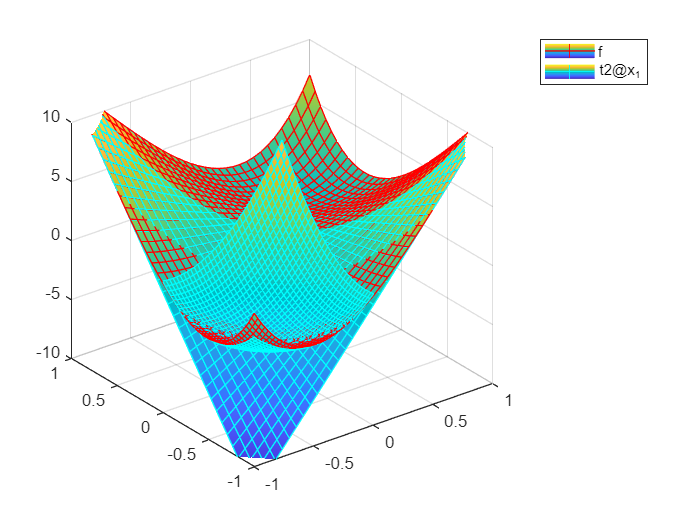

fsurf(f, [-1, 0, -1, 0], 'EdgeColor', 'red');
hold on
fsurf(t1, [-1, 0, -1, 0], 'EdgeColor', 'Cyan');
zlim([-10 10]);
legend('f', 't2@x_1')
hold off

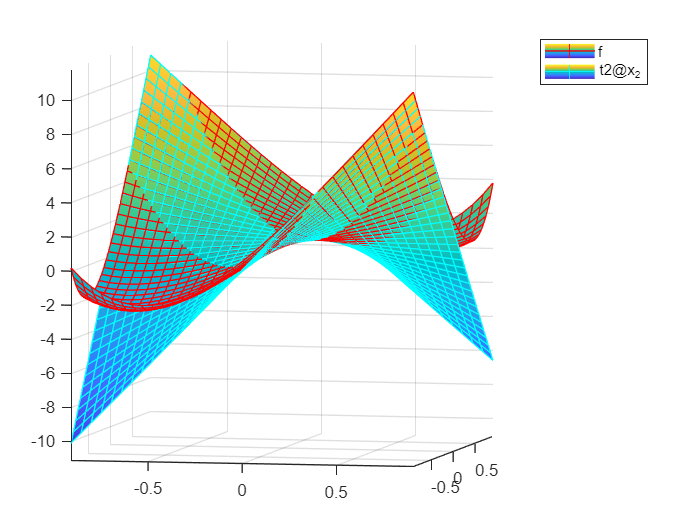

fsurf(f, [-1, 1, -1, 1], 'EdgeColor', 'red');
hold on
fsurf(t2, [-1, 1, -1, 1], 'EdgeColor', 'Cyan');
zlim([-10 10]);
legend('f', 't2@x_2')
hold off

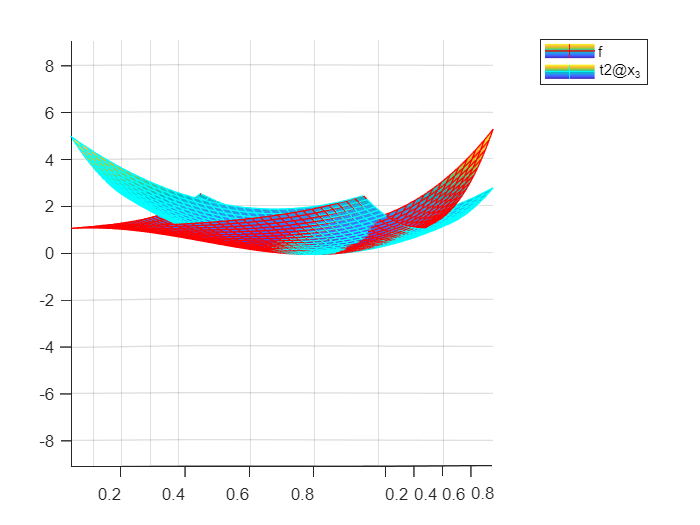

fsurf(f, [0, 1, 0, 1], 'EdgeColor', 'red');
hold on
fsurf(t3, [0, 1, 0, 1], 'EdgeColor', 'Cyan');
zlim([-10 10]);
legend('f', 't2@x_3')

This confirms not only that the taylor expansions are fitting on the original function, but also that the points were strong minimum, saddle point and strong minimum respectively.